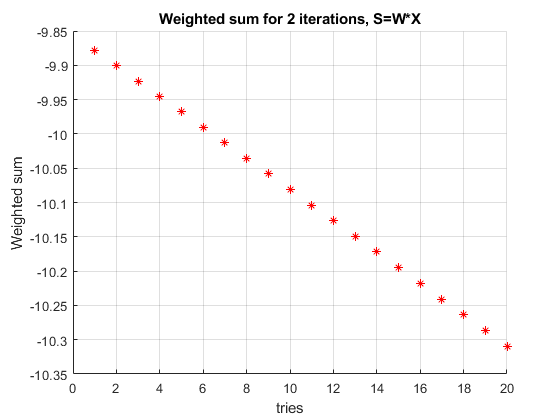

% Exercise 1. 

% evaluation will be made for 20 times simultaneously
tries = 20;
% lambda function to be applied on input dimention
polynom = @(x) power(x,4) + power(x,3) + power(x,2) + power(x,1) + power(x,0);
% An space dimention in range of [-1,1]
latent_space = linspace(-1,1,tries*100);
latent_space = reshape(latent_space, [tries,100]);
% Got points
points= polynom(latent_space);
% random weights
weights = randn(1,length(latent_space));

weighted_sum = points*weights';

%visualize
scatter(1:20,weighted_sum','r*');
grid;
xlabel('tries');
ylabel('Weighted sum')
title('Weighted sum for 2 iterations, S=W*X')

Here we visualized a simple linear model

% Exercise 2 

% input data
% our aim is to find a point where the error metric of the sum of the
% absolute differences between the value and the data points is minimum
data = rand(1,100).^4;

% candidate values
space = linspace(0,1,100);


% metric evaluation func
metric = @(x,y) sum(abs(data(:) - space));

% calculated metric for each candidate with the whole random input data
error_metric = metric(data,space);

% get the minimum
min_metric = min(error_metric)

min_metric = 18.9097

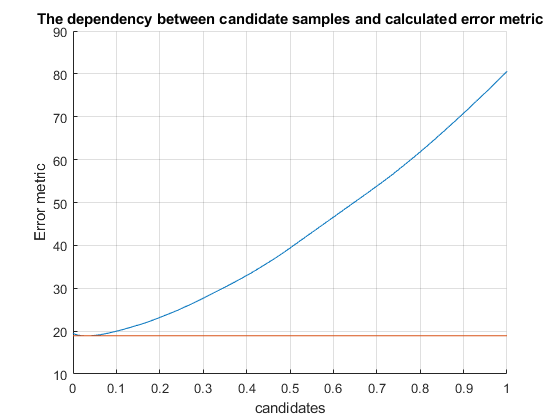


% visualize the dependency
figure;
hold on;
ax = axis;
plot(space, error_metric);
grid;
xlabel('candidates')
ylabel('Error metric');
title('The dependency between candidate samples and calculated error metric')

% visualize the minimum metric 
plot(ax(1:2),[min_metric min_metric])

Red line shows the intersection where the minimum error is ~19. Not very expressive, but still can be useful. 

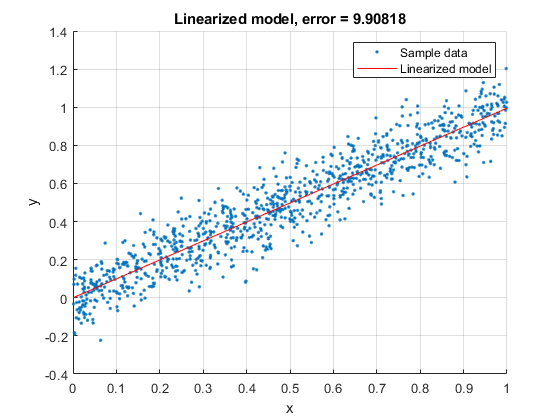

% Exercise 3

% random points
x = rand(1,1000);
% corresponding noisy function
y = x +0.1 * randn(1,1000);


% linearized model
X = x(:);

% figure 
figure;
ax = axis;
hold on;

r = scatter(x,y,'.');
% Conduct ordinary least-squared (OLS) to fit a line for the model
W = inv(X'*X)*X'*y(:);

% Model fit
modelfit = x*W;

% Squared error
error = sum((y(:) - modelfit').^2);

% Plot the fit model
xx = linspace(ax(1), ax(2), length(X))';
yy = xx*W;
model = plot(xx,yy,'r-');

legend([r,model], 'Sample data','Linearized model');grid;
xlabel('x')
ylabel('y')
title(sprintf('Linearized model, error = %g',error))

Here we used a randomized model and tried to reconstruct a linearized model.

That was quite successful, because visual observation shows that the red line (our fitted model) describes the data well


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality


     0          3         53224.7                      2.88e+04


     1          6         53224.7        1.88917       2.88e+04      


     2          9         53224.7       0.472292       2.88e+04      


     3         12         43813.7       0.118073       5.11e+04      


     4         15         32597.1       0.236146       1.76e+05      


     5         18         26612.6      0.0396605       1.97e+04      


     6         21         26464.4      0.0945094            841      


     7         24         26463.3      0.0379698           10.8      


     8         27         26463.3    0.000111675          0.022      


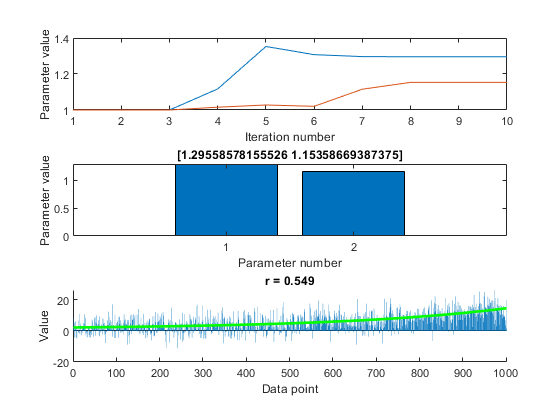


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the selected value of the function tolerance.

<stopping criteria details>



% Exercise 4

a = 1.3; b = 1;
x = 0:0.01:10;
y = a.^x + b+ 5*randn(size(x));

options = optimset('Display','iter','FunValCheck','on', ...
    'MaxFunEvals',Inf,'MaxIter',Inf, ...      
    'TolFun',1e-6, ...
    'OutputFcn', @(a,b,c) outputfcnplot(a,b,c,1,y));

paramslb = [0.0    0.0];    % lower bound
paramsub = [inf     inf];   % upper bound

%          a    b
params0 = [1.0    1.0];

costfun = @(pp) sqrt(abs(x-pp));

% Try to fit the nonlinear parametric model
modelfun = @(pp, xx) pp(1).^x + pp(2);

[params, resnorm, residual, exitflag, output] = lsqcurvefit(modelfun,params0,x,y, paramslb, paramsub, options);

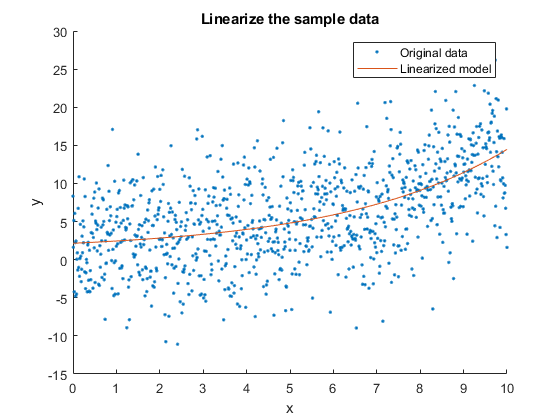

% Visualize the raw data and the fit model
figure;
hold on;
x_fig = scatter(x,y,'.');

xx = x(:);
yy = modelfun(params, xx);
model_fig = plot(xx,yy);
xlabel('x');
ylabel('y');
legend([x_fig model_fig],'Original data','Linearized model');
title("Linearize the sample data");

Here our aim is to recostruct a linearized model with embedded Matlab functions with the least-squares technique.

Depending on the slope of the original model, the fitted model will also change along the input data.

% Exercise 5

% To understand, see https://www.analyticsvidhya.com/blog/2018/08/k-nearest-neighbor-introduction-regression-python/
% https://es.coursera.org/lecture/ml-regression/1-nearest-neighbor-regression-approach-ddazj


% But there is a question
% If we are given a x-coordinate where predict y-coordinate at, don't we
% always to mistaken in prediction?

N = 10;

%x = linspace(1,100,N)
x =  linspace(1,100,N)

x =      1    12    23    34    45    56    67    78    89   100


y =  x.^2 +x + 23 + 5000*rand(1, length(x));

%xx = [1 3 5 123 455 23 19];
xx = linspace(1,100,1000)

xx =     1.0000    1.0991    1.1982    1.2973    1.3964    1.4955    1.5946    1.6937    1.7928    1.8919    1.9910    2.0901    2.1892    2.2883    2.3874    2.4865    2.5856    2.6847    2.7838    2.8829    2.9820    3.0811    3.1802    3.2793    3.3784    3.4775    3.5766    3.6757    3.7748    3.8739    3.9730    4.0721    4.1712    4.2703    4.3694    4.4685    4.5676    4.6667    4.7658    4.8649    4.9640    5.0631    5.1622    5.2613    5.3604    5.4595    5.5586    5.6577    5.7568    5.8559


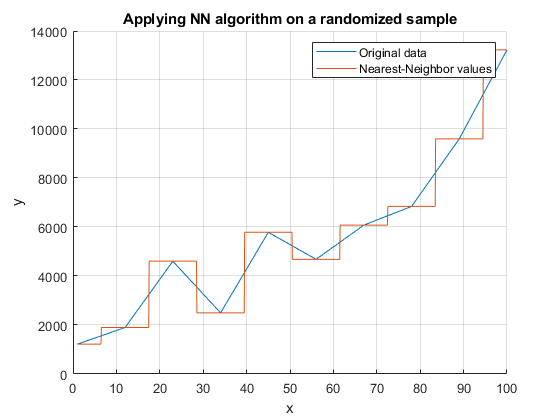


yy = nnregress(xx,x,y);

figure;
hold on;grid;
d = plot(x,y);
nn = plot(xx,yy);
xlabel('x');
ylabel('y');
legend([d,nn],'Original data', 'Nearest-Neighbor values');
title('Applying NN algorithm on a randomized sample');

Sometimes we are unable to predict shape of the model, or the model is very complicated. Another technique is nearest-neignbor, which just finds the most appropriate point for a specific input. Nearest-neighbor is highly depends on the data, the bigger training data set we have, the more precise model can be, but it then may be overfitted.